EP14 - Projeto do controlador PI e PD via lugar das raízes

Data: 14 de maio

ARTHUR LORENCINI BERGAMASCHI

PEDRO GABRIEL GAMBERT DA SILVA

Usar rlocus ou rltool para os projetos.

1) Verifique o efeito do zero de um controlador PD sobre as respostas deste sistema, **escolhendo Kp e Kd de forma a obter a resposta mais rápida possível com UP<10%**. Não há especificação de erro em regime.

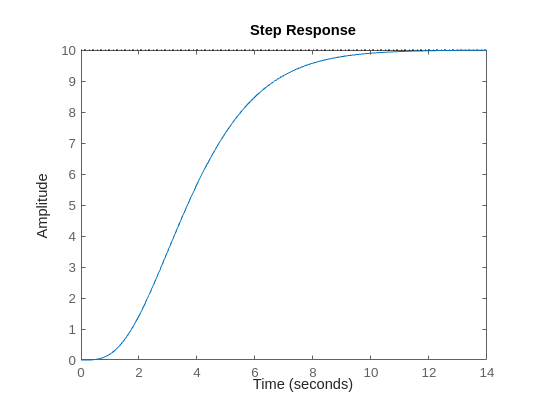

s = tf('s');
g = 10/(s+1)^4;
step(g)

Vemos que o tempo para chegar na amplitude 10 é de uns 10 segundos.

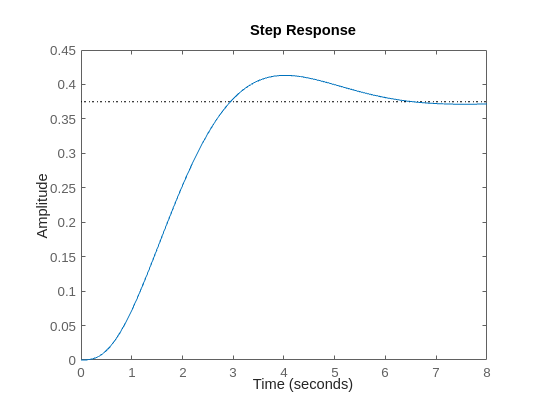

% Fixando kp_1 em 0.06, achamos (via rltools)
% um bom zero em -0.6, logo
% kd_1 = kp_1/zero → kd_1 = 0.06/0.6 = 0.1
kp_1 = 0.06;
kd_1 = 0.1;
c_1 = kp_1 + (kd_1*s);
m_1 = feedback(c_1*g,1);
step(m_1)

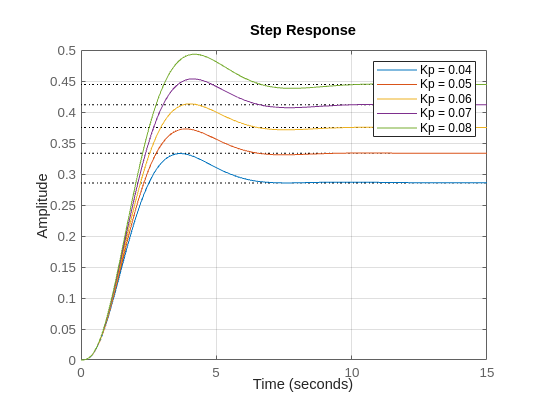

% É notório que o erro em regime ficou uma porcaria. 
% Entretanto, o ts ficou em 5.92s e UP em 9.88%
% Definindo os limites e o número de elementos
% Definindo os valores
x = 0.06;
a = 0.01;
t = 0:0.1:15; 

% Criando o vetor
figure;
hold on;
vetor = [x-2*a, x-a, x, x+a, x+2*a];
legendas = {};
for kp = vetor
    c = kp + (kd_1*s);
    m = feedback(c*g,1);
    step(m,t)
    legenda = ['Kp = ', num2str(kp)]; % Criando a legenda
    legendas = [legendas, legenda];
end
legend(legendas); % Adicionando a legenda
grid on;
hold off;

2) Plote a saída e o sinal de controle para uma entrada degrau no mesmo gráfico, analisando.

t = 0:0.1:15; 
u = (1 - m_1)*c_1 % U = E*C; E = R - Y; M = R/Y

u =
 
  0.1 s^5 + 0.46 s^4 + 0.84 s^3 + 0.76 s^2 + 0.34 s + 0.06
  --------------------------------------------------------
              s^4 + 4 s^3 + 6 s^2 + 5 s + 1.6
 
Continuous-time transfer function.
Model Properties


É notório obervar que U(s) é não causal. Logo, precisamos adicionar um filtro (ou um pólo, como queira chamar) para deixar o sinal de controle causal. O pólo tem que ficar mais a esquerda do eixo real para que seu efeito seja mínimo sobre o LR.

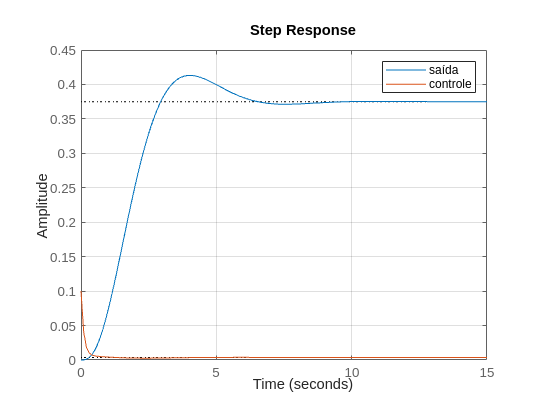

f = 1/(s+10); % LPF
figure;
hold on;
step(m_1,u*f,t)
legend('saída','controle')
grid on
hold off;

3) Verifique o efeito do zero de um controlador PI sobre as respostas deste sistema, escolhendo Kp e Ki de forma a obter a resposta mais rápida possível com UP<10%.

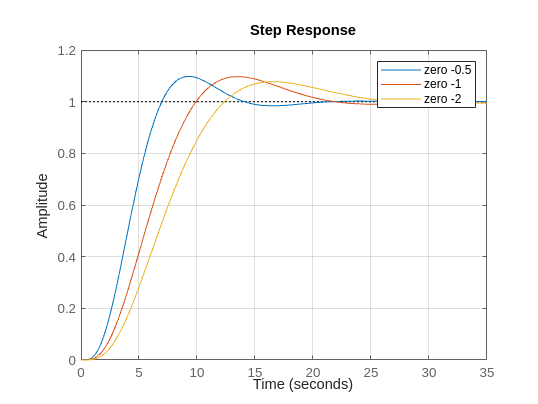

% Variando kp para cada sistemas com zeros em -0.5, -1, e 2;
kp_1 = 0.054;
kp_2 = 0.02;
kp_3 = 0.008;
c_1 = kp_1*(s+ 0.5)/s; % zero em -0.5
c_2 = kp_2*(s+ 1)/s; % zero em -1
c_3 = kp_3*(s + 2)/s; % zero em -2
m_1 = feedback(c_1*g,1);
m_2 = feedback(c_2*g,1);
m_3 = feedback(c_3*g,1);
step(m_1,m_2,m_3)
legend('zero -0.5','zero -1','zero -2')
grid on

Vemos que o zero em -0.5 dá a resposta mais rápida.

4) Plote no mesmo gráfico a saída e o sinal de controle para uma entrada degrau, analisando.

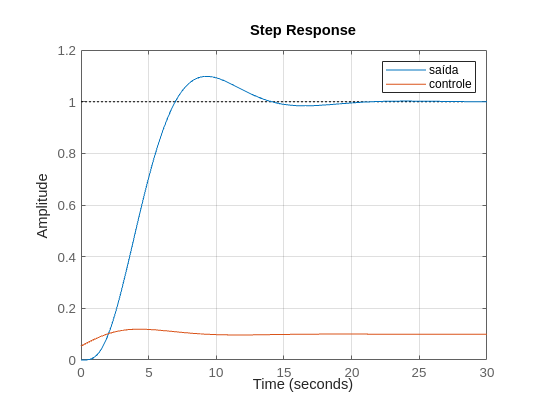

t = 0:0.1:30; 
% Sinal de Controle para R(s) = 1/s;
u = (1 - m_1)*c_1; % U = E*C; E = R - Y; M = R/Y
figure;
hold on;
step(m_1,u,t)
legend('saída','controle')
grid on
hold off;

5) Plote no mesmo gráfico a saída e o sinal de controle para uma entrada de distúrbio somada ao sinal de controle, analisando.

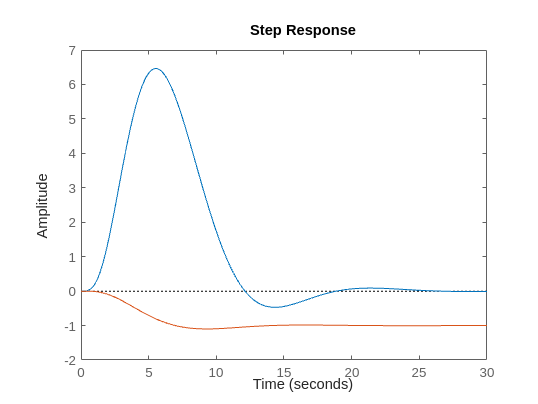

t = 0:0.1:30; 
y = g/(1+ c_1*g); % resposta da saída ao distúrbio;
u = -y*c_1; % sinal de controle para R(s) = 0;
step(y,u,t)

O sistema não consegue sumir com o distúrbio durante o período transitório. O controlador é capaz apenas de zerar o efeito do distúrbio para o regime permanente. Tô certo!!!!